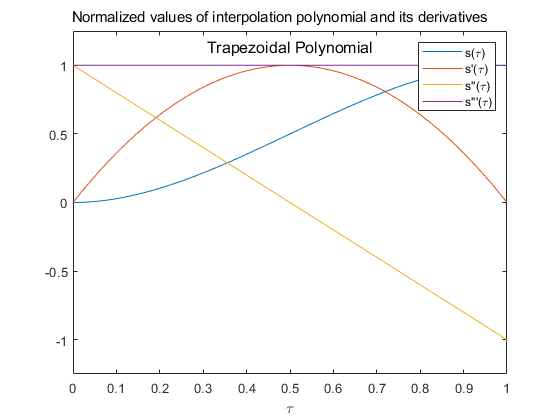

clc, clear
tau = 0:0.01:1;

% Trapezoidal smooth
s = -2*tau.^3 + 3*tau.^2;
sp = -6*tau.^2 + 6*tau;
spp = -12*tau + 6;
sppp = -12*tau.^0;
plotter(tau, s, sp, spp, sppp, "Trapezoidal Polynomial");

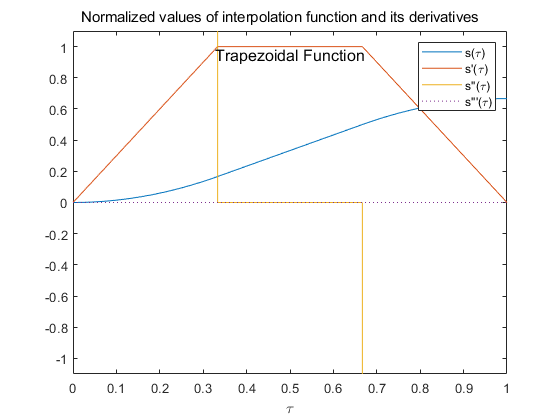


% Trapezoidal sharp
syms t
S = 1;      % maximum speed in rad/s
s = 3*S/2*t^2 - 3*S/2*(t-1/3)^2 * heaviside(sym(t - 1/3)) - 3*S/2*(t - 2/3)^2 * heaviside(sym(t - 2/3));
sp = diff(s, t);
spp = diff(sp, t);
sppp = diff(spp, t);

figure;
fplot(s); hold on;
fplot(sp); hold on;
fplot(spp); hold on;
fplot(sppp, 'LineStyle', ':'); hold on;
xlim([0, 1])
ylim([-1.1, 1.1])
legend('s(\tau)', "s'(\tau)", "s''(\tau)", "s'''(\tau)")   
title = "Normalized values of interpolation function and its derivatives";
sgtitle(title, 'FontSize', 11, 'FontWeight', 'light')
text(0.5, 0.95, "Trapezoidal Function", 'HorizontalAlignment', 'center', 'FontSize', 12)
xlabel("\tau")

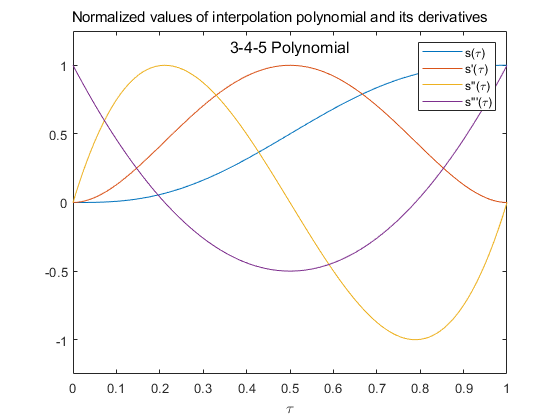


% s = 3*S/2*tau.^2 - (3*S/2*(tau - 1/3).^2).*heaviside(tau - 1/3) - (3*S/2*(tau - 2/3).^2).*heaviside(tau - 2/3);
% sp = 3*S*tau.^1 - (3*S*(tau.^1 - 1/3)).*heaviside(tau - 1/3) - (3*S*(tau.^1 - 2/3)).*heaviside(tau - 2/3);
% figure;
% plot(tau, s); hold on;
% plot(tau, sp) 
% legend('s(\tau)', "s'(\tau)")

% 3-4-5
s = 6*tau.^5 + -15*tau.^4 + 10*tau.^3;
sp = 30*tau.^4 - 60*tau.^3 + 30*tau.^2;
spp = 120*tau.^3 - 180*tau.^2 + 60*tau;
sppp = 360*tau.^2 - 360*tau + 60;
plotter(tau, s, sp, spp, sppp, "3-4-5 Polynomial");

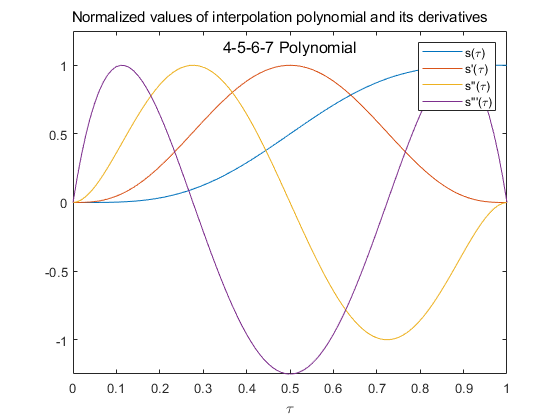


% 4-5-6-7
s = -20*tau.^7 + 70*tau.^6 + -84*tau.^5 + 35*tau.^4;
sp = -140*tau.^6 + 420*tau.^5 - 420*tau.^4 + 140*tau.^3;
spp = -840*tau.^5 + 2100*tau.^4 - 1680*tau.^3 + 420*tau.^2;
sppp = -4200*tau.^4 + 8400*tau.^3 - 5040*tau.^2 + 840*tau.^1;
plotter(tau, s, sp, spp, sppp, "4-5-6-7 Polynomial");

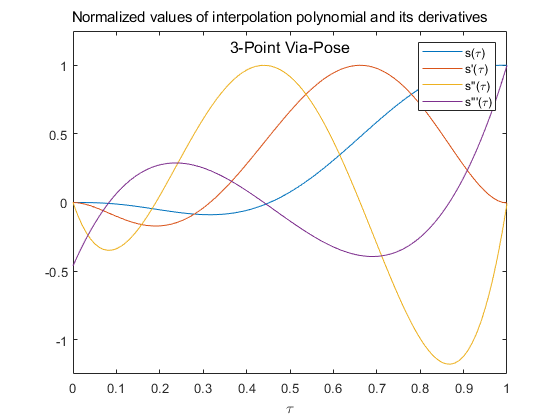


% via-pose
s = 27.13*tau.^6 - 75.40*tau.^5 + 66.40*tau.^4 - 17.13*tau.^3;
sp = 162.78*tau.^5 - 377*tau.^4 + 265.6*tau.^3 - 51.39*tau.^2;
spp = 813.9*tau.^4 - 1508*tau.^3 + 796.8*tau.^2 - 102.78*tau.^1;
sppp = 3255.6*tau.^3 - 4524*tau.^2 + 1593.6*tau.^1 - 102.78*tau.^0;
plotter(tau, s, sp, spp, sppp, "3-Point Via-Pose");

function [] = plotter(tau, s, sp, spp, sppp, name)
figure;
plot(tau, s); hold on;
plot(tau, sp/max(sp)); hold on;
plot(tau, spp/max(spp)); hold on;
plot(tau, sppp/max(sppp))
legend('s(\tau)', "s'(\tau)", "s''(\tau)", "s'''(\tau)")   
title = "Normalized values of interpolation polynomial and its derivatives";
sgtitle(title, 'FontSize', 11, 'FontWeight', 'light')
text(0.5, 1.14, name, 'HorizontalAlignment', 'center', 'FontSize', 12)
xlabel("\tau")
ylim([-1.25, 1.25])
end